# Calcolo Numerico con Laboratorio

# Compito a casa 

# 20 settembre 2021

## Esercizio 1

Riportare in una figura i grafici delle funzioni $f(x)=\frac{x\,\rm{arctg}(x)}{2(e^{x^2-1}-x+1)}$e $g(x)=\left(\frac{x^2}6-1\right)\cos(2x)$ per $x\in[-1,3]$. Completare la figura con titolo e legenda.

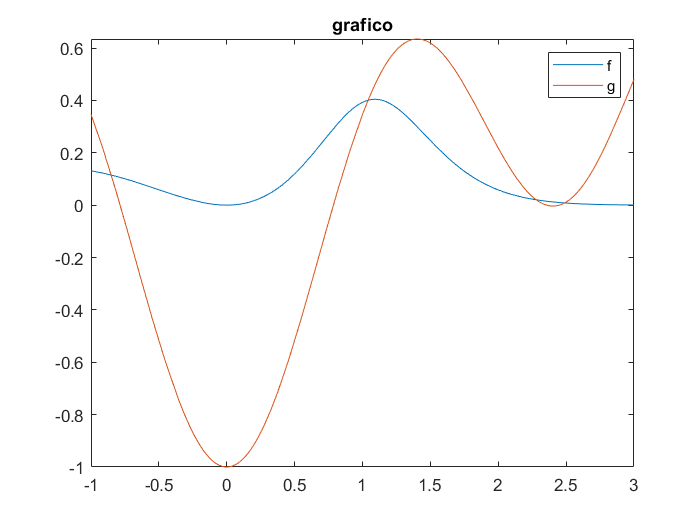

clear all
close all
f=@(x) (x.*atan(x))./(2*(exp(x.^2-1)-x+1));
g=@(x) (x.^2/6-1).*cos(2*x);
fplotSave({f,g},[-1 3],"grafico",["f","g"])

## Esercizio 2

- Fare il grafico in 3D della superficie $f(x,y)=\sin(x)+\cos(y)$ per $x\in[-\pi,\pi]$, $y\in[0,4\pi]$. Usare poi il comando f`contour `per fare il grafico delle curve di livello.

- Plottare le linee di livello della funzione $f(x,y)=\sin(x)\cos(y)$ sul dominio di default con passo 0.1.

- Plottare le linee di livello della funzione $f(x,y)=y\sin(x)-x\cos(y)$ sul quadrato di lato $[-2\pi,2\pi]$.

- Plottare la linea di livello 0 delle funzioni $f(x,y)=x^2+y^2-4$ e $g(x,y)=x^2-y^2$ su uno stesso grafico.

clear all
close all
f=@(x,y) sin(x)+cos(y);
int=[-pi,pi,0,4*pi];
fsurfSave({f},int,"grafico")
fcontourSave({f},0,"grafico")
f=@(x,y) sin(x).*cos(y);
fcontourSave({f},0,"grafico","","LevelStep",0.1)
f=@(x,y) y.*sin(x)-x.*cos(y);
fcontourSave({f},[-2*pi 2*pi],"grafico")


## Esercizio 3

Calcolare le radici reali di un'equazione di secondo grado: $ax^2+bx+c=0$.

**Procedura**

Prima si deve calcolare il discriminante: $\Delta=b^2-4ac$

Se $\Delta>0$ le radici sono

$x_1=\frac{-b+\sqrt{\Delta}}{2a}\quad

x_2=\frac{-b-\sqrt{\Delta}}{2a}$;

se $\Delta=0$ abbiamo due radici coincidenti di valore $x=-\frac{b}{2a}$;

se $\Delta<0$ non ci sono radici reali.

**Parte 1**

Scrivere uno file di tipo script per calcolare le radici dell'equazione di secondo grado.

Testare il risultato con i seguenti dati:

a=2; b=-3; c=1;
a=4; b=4; c=1;
a=1; b=2; c=2;
a=0; b=5; c=-2;
semilogySave({2:20},{4:22},"grafico")

**Parte 2**

Per $\alpha=2, 7, 12, 16.3, 17$, risolvere l'equazione $x^2-2bx+c=0$ essendo $b=\frac{10^\alpha+1}2$ e $c=10^\alpha$. Per ogni valore di $\alpha$ le soluzioni sono $x_1=1$ e $x_2=10^\alpha$. Motivare le soluzioni ottenute.